%% Roshan Jaiswal-Ferri
%Section - 01
%Aero 356 Midterm 3: 6/7/25

%% Workspace Prep

%warning off
format long     %Allows for more accurate decimals
close all;      %Clears all
clear all;      %Clears Workspace
clc;            %Clears Command Window

# Assumptions & Constants:

k = 1.38*10^-23 J/K

charge = +/- 1.6e-19 C

permitivity of free space = 8.8 × 10-12 m-3 kg-1 s4 A2

mi = 1.67*10^-27 kg

me = 9.11*10^-31 kg

kb = 1.38*10^-23; %J/K
q = 1.6e-19; %C
perm = 8.8*10^-12; %m-3 kg-1 s4 A2
mi = 1.67*10^-27; %kg
me = 9.11*10^-31; %kg
Re = 6378;

# Question 1) 

Consider a spherical spacecraft with a radius of 0.5m, orbiting  Earth at 300km. The ambient plasma temperature is 1500K and the plasma  density is 5x10^11 m^-3.  Assume no backscattering, no secondary  emission, and no conduction currents.

a) Plot (and attach the plot here) the electron and ion currents due  to the spacecraft during eclipse for spacecraft voltages of -1V to 0V. 

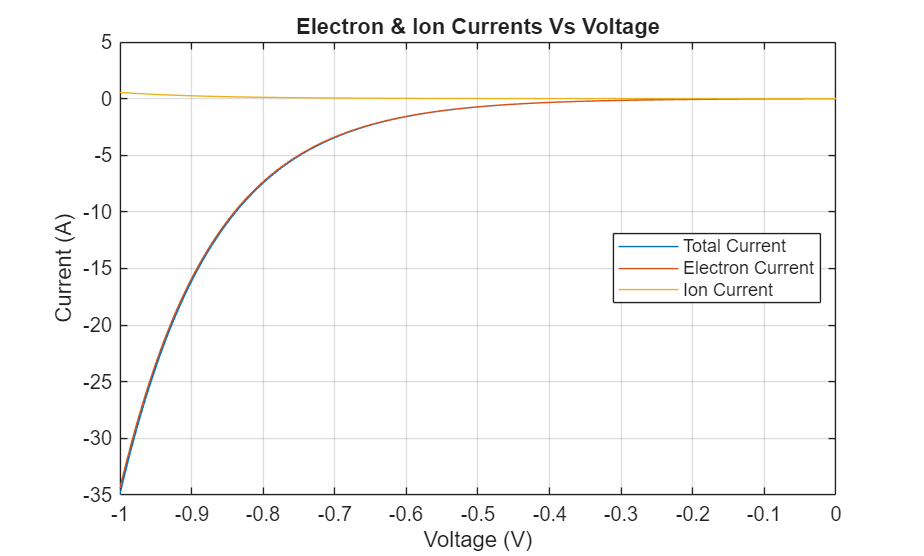

V = linspace(-1,0,200);
Ise = 0;
Isi = 0;
Ibse = 0;
Ic = 0;
Iph = 0; %zero bc eclipse

pT = 1500; %k
n = 5e11;
ni = n;
ne = n;

Ae = 4*pi*0.5^2;
Ai = 0.25*Ae;

Vth_e = sqrt((8*kb*pT)/(pi*me));
Vth_i = sqrt((8*kb*pT)/(pi*mi));

Ieo = 0.25*-q*ne*Vth_e;
Iio = 0.25*q*ni*Vth_i;

Ie = Ieo*Ae*exp((-q.*V)/(kb*pT));
Ii = Iio*Ai*exp(1-((q.*V)/(kb*pT)));


It = Ie - Ii - Ise - Isi - Ibse - Iph + Ic;


figure('Name','Electron & Ion Currents Vs Voltage')
plot(V,It)
hold on
grid on
plot(V,Ie)
plot(V,Ii)
xlabel('Voltage (V)')
ylabel('Current (A)')
title('Electron & Ion Currents Vs Voltage')
legend('Total Current', 'Electron Current', 'Ion Current',Location='best')

# Question 1 b) 

What value do you expect the spacecraft potential to float  to? Identify analytically (via formula).  Give results to three decimal  places in V. 

r = 300;
mu = 398600;
vsc = sqrt(mu/(r+Re));
vsc = vsc*1000;

%pT = 5000;
inside = vsc* sqrt((pi*me)/(8*kb*pT));
Vf = ((kb*pT)/q)*log(inside);
disp(['Floating Potential (V): ', num2str(Vf)])

Floating Potential (V): -0.44483


# Question 1 d) 

Calculate the debye length [m] Provide your answers in 4 decimal places.

deb = sqrt((perm*kb*pT)/(ne*q^2));
disp(['Debye Length (m): ', num2str(deb)])

Debye Length (m): 0.0037724


# Question 1 e) 

Calculate the Plasma Parameter [unitless] with no decimals

pparameter = (4/3)*pi*(deb^3)*ne;
disp(['Plasma Parameter (unitless): ', num2str(pparameter)])

Plasma Parameter (unitless): 112440.6081


# Question 1 f) 

what is the floating voltage of a spacecraft if you move the spacecraft to GEO? Give results in V with no decimals. Credit for this problem will be partially dependent on the work shown in the pdf.

alt = 36000; %new geo altitude in km
rsc = Re + alt;
n = 10^7;
Te = 10^7; %k

syms Vf2
eq = Vf2 == ((kb*Te)/-q)*log(-1*sqrt(1)*1*(1-((q*Vf2)/(kb*Te))));
soln = solve(eq,Vf2);
Vf2 = double(soln); %in GEO the Vf is way higher so ~1000 volts makes sense
disp(['Floating Potential (GEO) (V): ', num2str(Vf2)])

Floating Potential (GEO) (V): 1102.6757
